# **MATLAB Review**

### **For MEAM Sophmores**

*By Mathew Halm, Walker Gosrich, Philip Sieg*

### Introduction

This review is meant to prepare students of all backgrounds for MEAM 200 level courses that will require some coding in MATLAB. If you have any specific questions throughout the course, please reach out to your TA's and peers on Piazza. This review aims to be as concise as possible, while also touching on important topics you will need. Remember, you can look up any function in the search bar to pull up its complete documentation.

%Note, this is a comment
%It is triggered by a '%' sign and any text on the same line
% following it is ignored when running your programs

In MATLAB, semicolons are used to supress printing to the terminal

x = 4

x = 4

y = 5;

### Math Operations

#### Basic Arithmetic

2+7     %Addition

ans = 9

7-3     %Subtraction

ans = 4

4*5     %Multiplication

ans = 20

20/10   %Division

ans = 2

2^3     %Exponentation

ans = 8

pi      %3.14.....

ans = 3.1416

Matlab follows standard order of opertations

100 / (5 * 2) ^ 2

ans = 1

#### Transcendental Functions

exp(2)      %e^2

ans = 7.3891

sin(pi/4)   %sine with radian input

ans = 0.7071

sind(45)    %sine with degree input

ans = 0.7071

### Vectors

Vectors are enclosed in brackets delimited by comas. 

v = [1, 4, -8]

v =      1     4    -8


w = [4, 6, 3]

w =      4     6     3


#### Standard Vector Operations

DP = dot(v, w)      %dot product, alternatively v' * w 

DP = 4

CP = cross(v, w)    %cross product

CP =     60   -35   -10


n = norm(v)         %l2 norm of vector

n = 9

#### Vectorization

Vectorization can be used to easily access 

v = 1:10            %vector containing entries with values 1-10

v =      1     2     3     4     5     6     7     8     9    10


w = 2:2:8           %vector containing entries 2-8 skipping by 2

w =      2     4     6     8


The linspace command can be used to create an evenly spaced vector between two bounds

v = linspace(0, 25, 50)    %left bound, right bound, vector size

v =          0    0.5102    1.0204    1.5306    2.0408    2.5510    3.0612    3.5714    4.0816    4.5918    5.1020    5.6122    6.1224    6.6327    7.1429    7.6531    8.1633    8.6735    9.1837    9.6939   10.2041   10.7143   11.2245   11.7347   12.2449   12.7551   13.2653   13.7755   14.2857   14.7959   15.3061   15.8163   16.3265   16.8367   17.3469   17.8571   18.3673   18.8776   19.3878   19.8980   20.4082   20.9184   21.4286   21.9388   22.4490   22.9592   23.4694   23.9796   24.4898   25.0000


### Matrices

Matrices are enclosed in brackets and rows are delimited by semicolons

A = [5, 9, 2; 4, 5, 2; 5, 8, -12] %3x3 matrix

A =      5     9     2
     4     5     2
     5     8   -12


#### Matrix Construction Shortcuts

eye(4)      %4x4 identity matrix (I_4)

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


ones(2,4)   %2x4 matrix of all 1's

ans =      1     1     1     1
     1     1     1     1


zeros(3,2)  %3x2 matrix of all 0's

ans =      0     0
     0     0
     0     0


rand(2)     %2x2 matrix of random numbers between [0, 1]

ans =     0.2599    0.4314
    0.8001    0.9106


#### Matrix Operations

B = [1, 5, 6; -2, 0, 3]

B =      1     5     6
    -2     0     3


B*A     %Matrix multiplication

ans =     55    82   -60
     5     6   -40


3.*A    %use a dot before the operation to perform element wise operations

ans =     15    27     6
    12    15     6
    15    24   -36


A^2     %A*A

ans =     71   106     4
    50    77    -6
    -3   -11   170


A.^2    %Each element in A gets squared

ans =     25    81     4
    16    25     4
    25    64   144


A + A   %Matrix addition

ans =     10    18     4
     8    10     4
    10    16   -24


B'      %Transpose of B

ans =      1    -2
     5     0
     6     3


inv(A)  %inverse of A

ans =    -0.4872    0.7949    0.0513
    0.3718   -0.4487   -0.0128
    0.0449    0.0321   -0.0705


det(A)  %determinant of A

ans = 156

Block Concatenation 

%[1, 0, 0, 0; 
% 0, 1, 0 ,0]
[eye(2), zeros(2,2)] 

ans =      1     0     0     0
     0     1     0     0


### Indexing Vectors and Matrices

Unlike other languages, **indexing begins with 1**

v(1)            %first element of v

ans = 0

v(end)          %last element of v

ans = 25

A(2,3)          %element of A in 2nd row, 3rd column

ans = 2

A([1, 2, 4])    %1st, 2nd and 4th elements of A

ans =      5     4     9


You can use vecotrization when indexing vectors and matrices

B(1:2:end)      %odd elements of B

ans =      1     5     6


### Linear Algebra

Solve the system Ax = b for x

A = rand(3)

A =     0.1818    0.1361    0.5499
    0.2638    0.8693    0.1450
    0.1455    0.5797    0.8530


b = rand(3,1)

b =     0.6221
    0.3510
    0.5132


x = A \ b       %backslash operator

x =     2.3033
   -0.3722
    0.4617


Finding eigenvectors and eigenvalues

[V, D] = eig(A)     %diagonal matrix D of eigenvalues

V =     0.4261    0.9019    0.7639
    0.4969   -0.4014   -0.5156
    0.7560    0.1599    0.3880


D =     1.3161         0         0
         0    0.2188         0
         0         0    0.3693


                    %matrix V whose colums are the corresponding right eigenvectors

### Plotting

t = 0:0.01:8

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


y = sin(t)

y =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0699    0.0799    0.0899    0.0998    0.1098    0.1197    0.1296    0.1395    0.1494    0.1593    0.1692    0.1790    0.1889    0.1987    0.2085    0.2182    0.2280    0.2377    0.2474    0.2571    0.2667    0.2764    0.2860    0.2955    0.3051    0.3146    0.3240    0.3335    0.3429    0.3523    0.3616    0.3709    0.3802    0.3894    0.3986    0.4078    0.4169    0.4259    0.4350    0.4439    0.4529    0.4618    0.4706


Create a new figure and polulate it

figure();
plot(t,y)   %independant variable, dependant variable

Allow for multiple plots on the same figure and plot another function

hold on
plot(t, 2*y, 'g', 'LineWidth', 2)   %plot the function with the color green 
                                    %and set the line width

Add labels, a title, and a legend to the plot

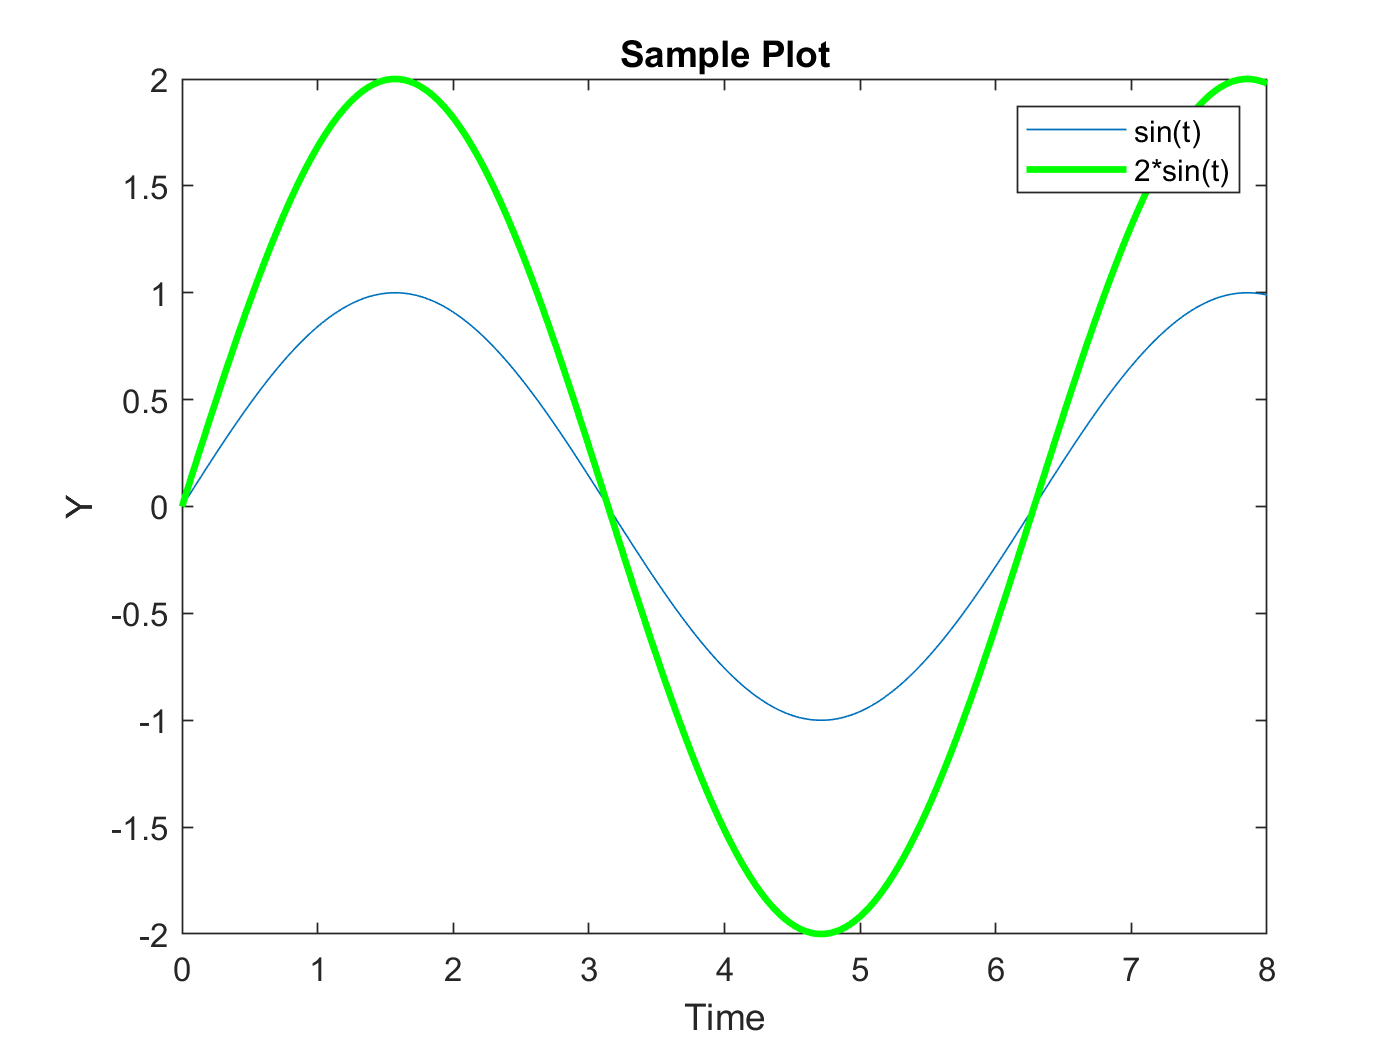

xlabel("Time")
ylabel("Y")
title("Sample Plot")
legend("sin(t)", "2*sin(t)")

Change axis Limits

axis = ([0, 8, -2, 2])

axis =      0     8    -2     2


#### Subplots

Create the first subplot

figure
subplot(2,1,1)  %a 2x1 grid of subplots where this is the 1st plot
plot(t,y)
xlabel("Time")
ylabel("Y")
title("sin(t)")

Now add a second subplot

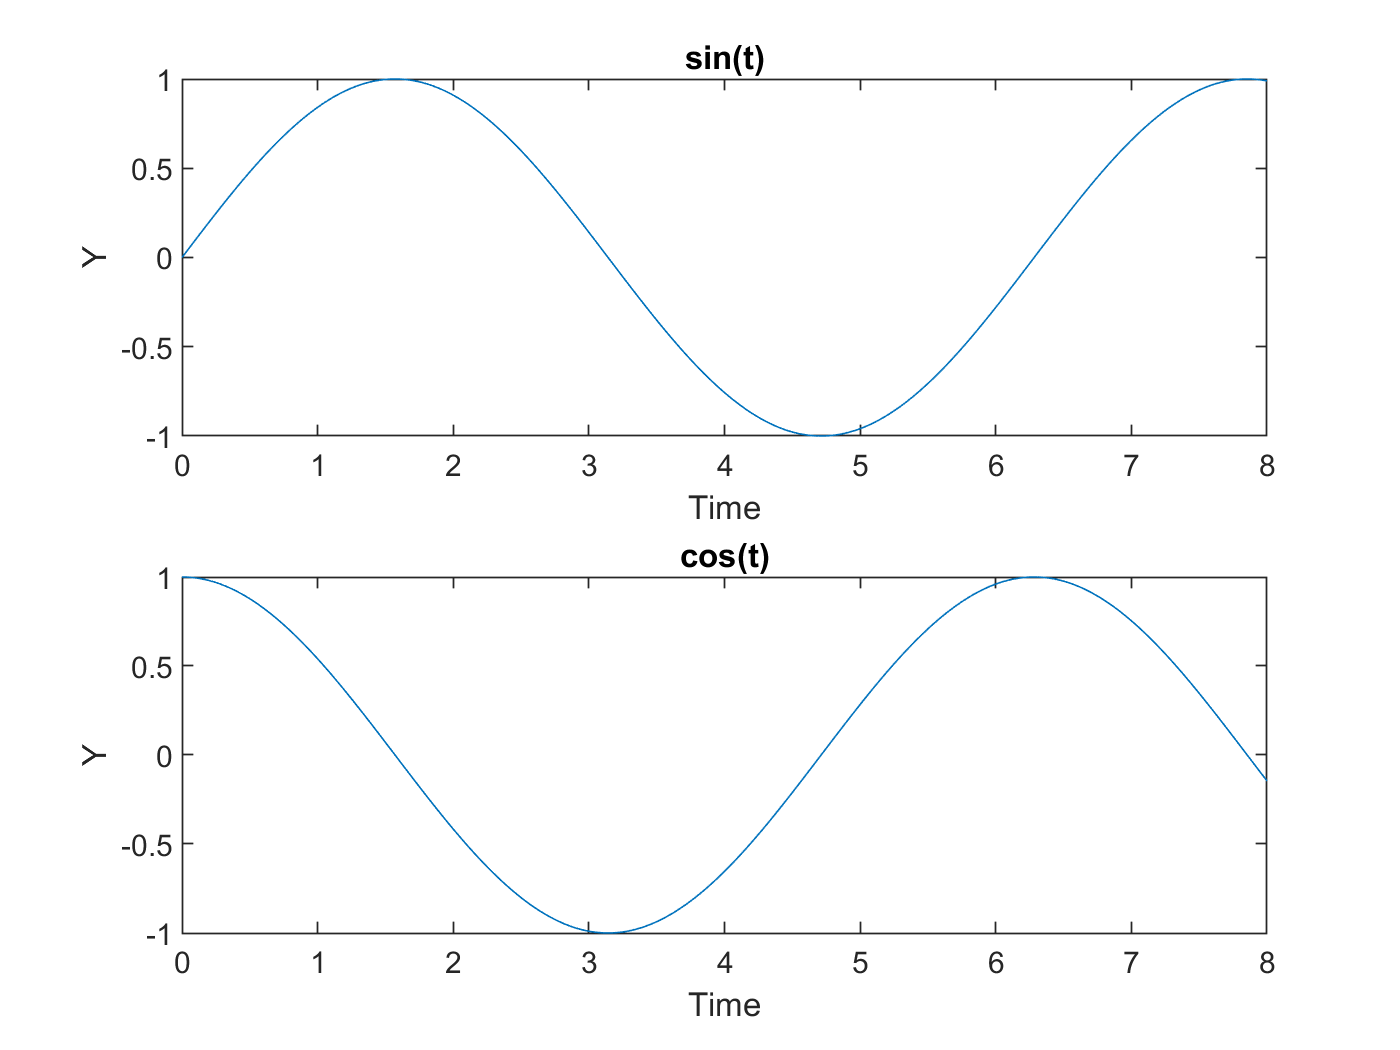

subplot(2, 1, 2) %a 2x1 grid of subplots where this is the 2nd plot
plot(t,cos(t))
xlabel("Time")
ylabel("Y")
title("cos(t)")

### Conditionals

Lets write a series of conditionals to find if a variable x is positive or negative

x = 43; %updated x and run to make sure this works for all cases

if x < 0
    disp("x is negative")
elseif x > 0    
    disp("x is positive")
else
    disp("x equals 0")
end

x is positive


### Loops

Lets implement a for loop to calculate the factorial of a number

n = 5; %number we want factorial of
factorial_for = 1;
for i = 1:n
    factorial_for = factorial_for * i;
end
factorial_for

factorial_for = 120

Lets do the same but with a while loop

factorial_while = 1;
j = 1;
while j <= n
    factorial_while = factorial_while * j;
    j = j + 1;
end
factorial_while

factorial_while = 120

### Functions

We can create functions in MATLAB as follows. Like in other languages, these are often written in seperate files. In this file, we can write it at the bottom of the function

%commented out so the code can compile, actual function decleration is at
%bottom of review
% function outputArg = timesMinusT(t, y)
%    outputArg = -t*y
% end 

Let call our function in a new script

timesMinusT(2,5) % expect to get 5 * -2 = -10

outputArg = -10

ans = -10

### Object Oriented Programming in MATLAB

For projects like Jenga and Arch, you will need to understand the basics of object orietented programming in MATLAB. Usually code written in MATLAB will not be object oreinted, but please see the sample code car.m

This file contains an example of creating a class for cars. 

## Appendix

Functions from above:

function outputArg = timesMinusT(t, y)
    outputArg = -t*y
end 
